# MA 423 Matrix Computations                    Lab - 7

## Name: Rasesh Srivastava

## Roll number: 210123072

format long e

## Question 1

### Exercise 4.2.19

Example 1:

A = randn(40, 17);
svd(A)

ans =      1.022806252335303e+01
     9.415150811958480e+00
     8.381588725281938e+00
     7.963951841922066e+00
     7.935210837070540e+00
     7.065308720777369e+00
     6.576113529988233e+00
     6.262713867444067e+00
     5.778978166540083e+00
     5.111335239579822e+00


rank(A)

ans =     17


#### Repeating the experiment 3 more times

Example 2:

A = randn(20, 9);
svd(A)

ans =      6.870859197563409e+00
     6.206550213475460e+00
     4.695776975545541e+00
     4.333676195493854e+00
     4.052080290733448e+00
     3.169642031827709e+00
     2.764857102471475e+00
     2.209991335038255e+00
     1.831472205253804e+00


rank(A)

ans =      9


Example 3:

A = randn(23, 15);
svd(A)

ans =      8.785256872508338e+00
     8.103349476443768e+00
     6.481549143195353e+00
     6.084745299189966e+00
     5.625197344980307e+00
     5.018649351113565e+00
     4.706856218028516e+00
     4.641123842388742e+00
     3.800987108053719e+00
     3.471701548709914e+00


rank(A)

ans =     15


Example 4:

A = randn(11, 11);
svd(A)

ans =      5.707979509306376e+00
     4.890423419480358e+00
     4.489452609603682e+00
     3.912538095168282e+00
     3.164084942334585e+00
     2.528540977455562e+00
     2.064900555527797e+00
     1.601896848578056e+00
     9.966179647859172e-01
     4.192357234232132e-01


rank(A)

ans =     11


This shows that a matrix chosen at random (nearly always) has full rank.

### Exercise 4.2.20

#### Part (a)

A = randn(8,4);
A(:,5:6) = A (:,1 : 2) + A (:,3:4);
[Q, R] = qr(randn(6));
A = A*Q

A =     -6.826515670825162e-01    -3.712672505243561e-02     6.205667910809892e-02     3.744853016070493e-01     2.797061604714663e-01     2.763630918348631e-01
     1.510485688362366e-01     4.322959720039935e-01     9.295850428340761e-01    -1.020735589796999e-01    -4.345613624336472e-02    -6.725137081396535e-01
     1.219006548695483e+00     1.524921179912380e-01     1.093515589996872e+00     7.317258633195661e-01    -1.195128771565205e+00    -1.700731128179729e+00
     7.057498032092578e-01    -7.291682327388086e-01     4.317837694554074e-01     3.718181331563638e+00    -1.874630876523513e+00    -2.767365912790917e+00
     8.937765525004648e-01    -9.360717207280768e-01    -5.795475221012700e-01     1.996525604252675e+00    -1.580539853441771e+00    -8.679492732572149e-01
     1.408858771355542e-01    -2.038581555633656e+00    -3.325992929809568e+00     1.302164460987007e+00    -9.892013059578225e-01     2.091223581881851e+00
     4.058275367560638e-02    -6.078062526214542e-01  

No, I cannot tell by looking at A that it has (numerical) rank 4.

#### Part (b)

format short e
svd(A)

ans =    6.4676e+00
   5.1879e+00
   1.7019e+00
   6.1423e-01
   5.3078e-16
   2.3879e-16


format long e
svd(A)

ans =      6.467631903324846e+00
     5.187920982579557e+00
     1.701894332584783e+00
     6.142313818909307e-01
     5.307830981689609e-16
     2.387887458775523e-16


4 singular values of A are "large" and 2 singular values of A are "tiny".

#### Part (c)

rank(A)

ans =      4


Used MATLAB 's rank command to confirm that the numerical rank is 4.

#### Part (d)

rank(A, 1e-17)

ans =      6


Used the rank command with a low enough threshold that it returned the value 6.

### Exercise 4.2.21

#### Part (a)

A = gallery('kahan', 90, 1.2, 0);
diagonal_elements = diag(A);
max_diagonal = max(diagonal_elements)

max_diagonal =      1


min_diagonal = min(diagonal_elements)

min_diagonal =      1.903869390462388e-03


if max_diagonal == 1 && min_diagonal > 0.001
    fprintf('The largest main-diagonal entry is 1, and the smallest is greater than 0.001.\n');
else
    fprintf('Conditions not satisfied.\n');
end

The largest main-diagonal entry is 1, and the smallest is greater than 0.001.


#### Part (b)

sig = svd(A);
format short e;


$$\sigma_1$$


sig(1)

ans =    8.7893e+00



$$\sigma_{89}$$


sig(89)

ans =    2.3842e-03



$$\sigma_{90}$$


sig(90)

ans =    3.9606e-15


Numerical rank of A = 89 (since $\sigma_{90}$ is comparable to u and $\sigma_{90}$ << 1, which implies that Numerical rank of A by SVD = 89)

rank(A)

ans =     89


MATLAB's opinion is also that numerical rank of A = 89

#### Part (c)

#### (i) For slightly perturbed version of the Kahan matrix

format long e;
A = gallery('kahan', 90, 1.2, 25);
sig = svd(A);
format short e;


$$\sigma_1$$


sig(1)

ans =    8.7893e+00



$$\sigma_{89}$$


sig(89)

ans =    2.3842e-03



$$\sigma_{90}$$


sig(90)

ans =    3.9606e-15


Numerical rank of A = 89 (since $\sigma_{90}$ is comparable to u and $\sigma_{90}$ << 1, which implies that Numerical rank of A by SVD = 89)

rank(A)

ans =     89


MATLAB's opinion is also that numerical rank of A = 89

#### (ii) For QR decomposition with column pivoting

[Q, R, E] = qr(A);
dif = norm(eye(90) - E, 2)

dif =      0


This implies that the permutation matrix E is the identity matrix, so no pivoting was done.

R(90, 90)

ans =    1.9039e-03


### Observations:

R(90, 90) is not roughly equal to the u (unit-round off) and also it is not very much less than 1.

Since we have used rank-revealing QR decomposition to obtain Q and R, it implies that the computed rank of the matrix is 90, which is evidently not true because the numerical rank of A is 89.

The correct rank of A as computed by MATLAB is 89 which is also reflected by the Singular Value Decomposition. (since $\sigma_{90}$ is comparable to u and $\sigma_{90}$ << 1, which implies that Numerical rank of A by SVD = 89). So, we deduce that the QR decomposition with column pivoting failed to detect the numerical rank deficiency of A.

Hence, Rank Revealing QR Decomposition is less efficient than the SVD method when detecting numerical rank deficiency.

## Question 2

load clown.mat;
[U, S, V] = svd(X);

Example image for k = 50

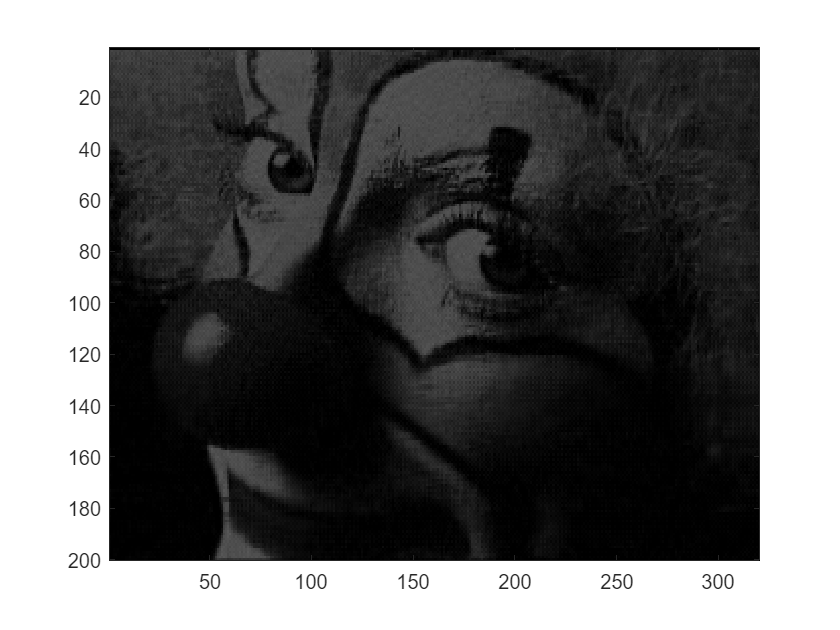

k = 50;
colormap('gray');
image(U(:, 1:k)*S(1:k, 1:k)*V(:,1:k)')

Making a table that records the relative errors and compression ratios for various different choices of k

k = (1:10:200);
k(end + 1) = 199;
[relative_error, compression_ratio] = deal([]);
for i = k
    compression_ratio(end + 1) = 520 * i / 64000;
    relative_error(end + 1) = S(i+1, i+1) / S(1, 1);
end
T = [k', compression_ratio', relative_error'];
T = array2table(T, 'VariableNames', {'k';'Compression Ratio';'Relative Error'});
disp(T);

        k         Compression Ratio    Relative Error
    __________    _________________    ______________

    1.0000e+00       8.1250e-03          2.5276e-01  
    1.1000e+01       8.9375e-02          6.7909e-02  
    2.1000e+01       1.7062e-01          3.8911e-02  
    3.1000e+01       2.5188e-01          2.6793e-02  
    4.1000e+01       3.3313e-01          2.1712e-02  
    5.1000e+01       4.1437e-01          1.8855e-02  
    6.1000e+01       4.9562e-01          1.6387e-02  
    7.1000e+01       5.7688e-01          1.4447e-02  
    8.1000e+01       6.5812e-01          1.2996e-02  
    9.1000e+01       7.3938e-01          1.1606e-02  
    1.0100e+02       8.2063e-01          1.0394e-02  
    1.1100e+02       9.0187e-01          9.3099e-03  
    1.2100e+02       9.8313e-01          8.1764e-03  
    1.3100e+02       1.0644e+00          7.1563e-03  
    1.4100e+02       1.1456e+00  

### Observations:

As the value of k increases, the relative error decreases and the compression ratio increases.